FolderPath = "D:\Workspace\DL for Computer Vision\Data\MathWorks Created\ASL Alphabet\Classification\Train";
ASLimds = imageDatastore(FolderPath, "IncludeSubfolders",true ,"LabelSource","foldernames");

[aslTrain, aslVal] = splitEachLabel(ASLimds, 0.8, "randomized");

resnet50 = imagePretrainedNetwork("resnet50", "NumClasses", 24);
inputSize = resnet50.Layers(1).InputSize;

augTrain = imageDataAugmenter(...
    'RandRotation', [-10 10], ...
    'RandXReflection', true, ...
    'RandYReflection', false, ...
    'RandXScale', [0.8 1.2], ...
    'RandYScale', [0.8 1.2], ...
    'RandXTranslation', [-20 20], ...
    'RandYTranslation', [-20 20]);
    
augTrain = augmentedImageDatastore(inputSize, aslTrain, 'DataAugmentation', augTrain);

augVal = augmentedImageDatastore(inputSize, aslVal);

numberOfTrainingImages = numel(aslTrain.Files);
iterationsPerEpoch = floor(numberOfTrainingImages / 150);

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss
    _________    _____    ___________    _________    ____________    ______________
            0        0       00:00:02        0.001                            3.4911
            1        1       00:00:02        0.001          3.4974                  
            3        1       00:00:04        0.001          3.5211            4.8421
            6        1       00:00:07        0.001          3.3231             3.899
            9        1       00:00:09        0.001          2.2037            7.2343
           12        1       00:00:10        0.001          2.1148            11.394
           15        1       00:00:11        0.001          2.9549            3.7861
           18        2       00:00:13        0.001           1.863            5.3995
           21        2       00:00:14        0.001          1.9099            5.0973
           24        2       00:00:16        0.001          1.727

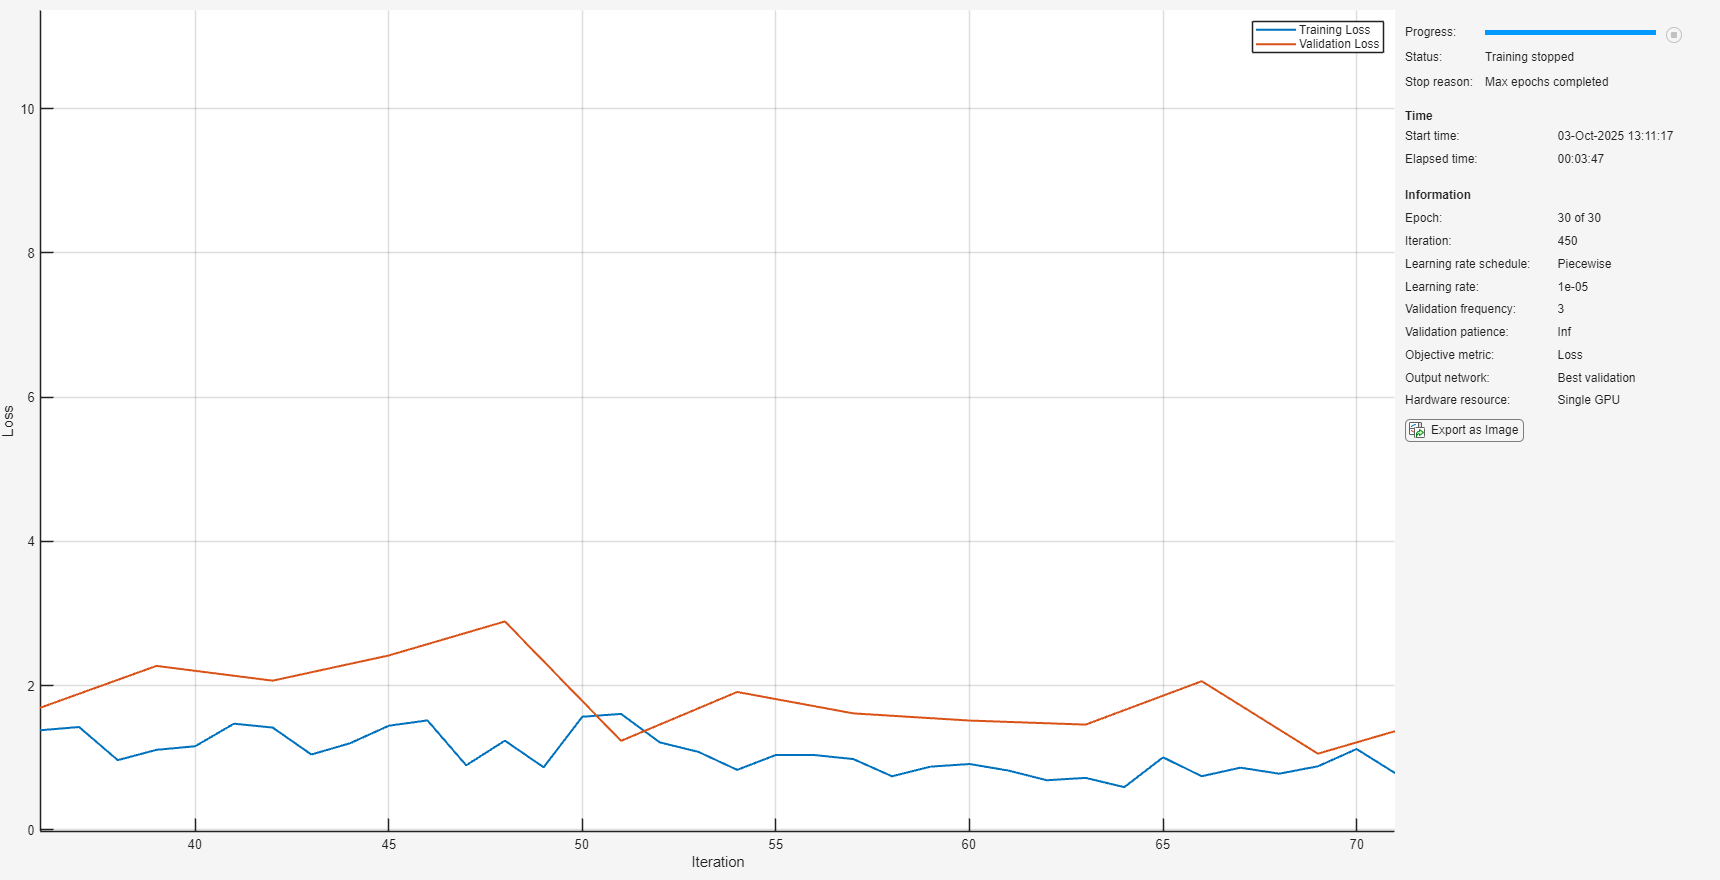

ASLClassifier =   dlnetwork with properties:

         Layers: [176×1 nnet.cnn.layer.Layer]
    Connections: [191×2 table]
     Learnables: [214×3 table]
          State: [106×3 table]
     InputNames: {'input_1'}
    OutputNames: {'fc1000_softmax'}
    Initialized: 1

  View summary with summary.


opts = trainingOptions("adam", ...
    "InitialLearnRate", 0.001, ...          % Add learning rate
    "LearnRateSchedule", "piecewise", ...   % Add scheduling
    "LearnRateDropPeriod", 10, ...
    "LearnRateDropFactor", 0.1, ...
    "ValidationData", augVal, ...
    "Shuffle", "every-epoch", ...
    "Plots", "training-progress", ...
    "OutputNetwork", "best-validation", ...
    "MiniBatchSize", 32, ...               % Reduce batch size
    "MaxEpochs", 30, ...                   % Add epoch limit
    "ValidationFrequency", iterationsPerEpoch, ...
    "L2Regularization", 0.001);            % Add regularization

ASLClassifier = trainnet(augTrain, resnet50, "crossentropy", opts)

testFolderPath = "D:\Workspace\DL for Computer Vision\Data\MathWorks Created\ASL Alphabet\Classification\Test";
testImds = imageDatastore(testFolderPath, "IncludeSubfolders",true, "LabelSource","foldernames");
length(testImds.Files)

ans = 240

augTest = augmentedImageDatastore(inputSize, testImds);
classNames = categories(testImds.Labels);

testPreds = minibatchpredict(ASLClassifier, augTest);
testPredsClasses = scores2label(testPreds, classNames);

testAccuracy = nnz(testPredsClasses == testImds.Labels) / length(testPredsClasses)

testAccuracy = 0.9500

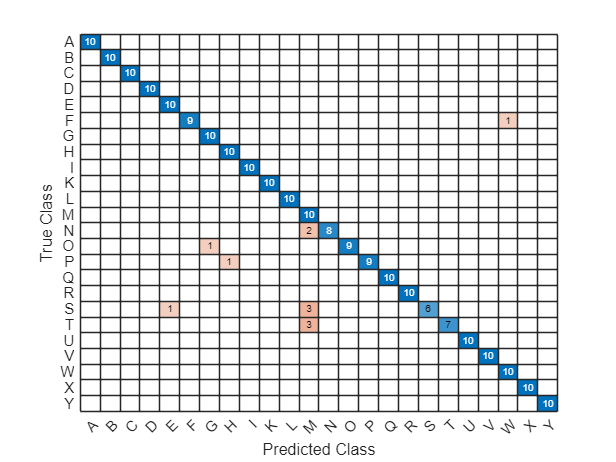

confusionchart(testImds.Labels, testPredsClasses)

img = read(ASLimds);
size(img)

ans =    300   300     3


testASLmodel(ASLClassifier)

Congratulations on training an accurate model!
Your answer code is: 23061912


unlabeledDataPath = "D:\Workspace\DL for Computer Vision\Data\MathWorks Created\ASL Alphabet\Classification\Unlabeled";
unlabeledImds = imageDatastore(unlabeledDataPath)

unlabeledImds =   ImageDatastore with properties:

                       Files: {
                              ' ...\ASL Alphabet\Classification\Unlabeled\unlabeled1.png';
                              ' ...\ASL Alphabet\Classification\Unlabeled\unlabeled2.png';
                              ' ...\ASL Alphabet\Classification\Unlabeled\unlabeled3.png'
                               ... and 6 more
                              }
                     Folders: {
                              ' ...\Data\MathWorks Created\ASL Alphabet\Classification\Unlabeled'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDatastoreImage


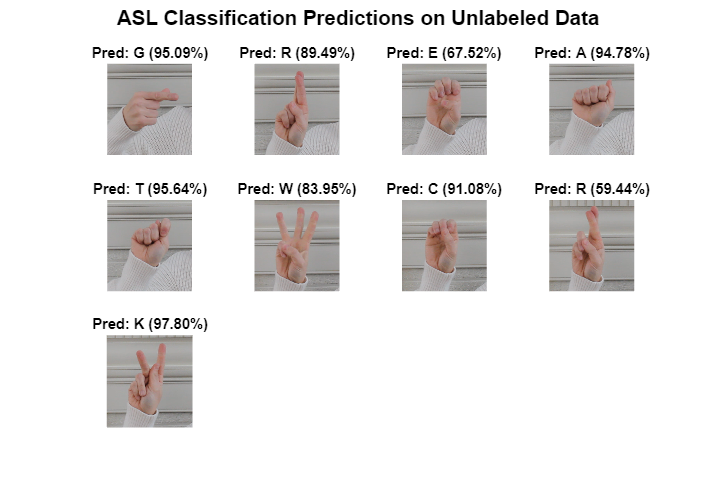

% Create augmented datastore for unlabeled images
augUnlabeled = augmentedImageDatastore(inputSize, unlabeledImds);

% Get predictions
unlabeledPreds = minibatchpredict(ASLClassifier, augUnlabeled);
unlabeledPredsClasses = scores2label(unlabeledPreds, classNames);

% Display results with images
figure('Position', [100, 100, 1200, 800]);
numImages = length(unlabeledImds.Files);
cols = 4;
rows = ceil(numImages / cols);

for i = 1:numImages
    subplot(rows, cols, i);
    
    % Read and display image
    img = readimage(unlabeledImds, i);
    imshow(img);
    
    % Get prediction and confidence
    [confidence, predIdx] = max(unlabeledPreds(i, :));
    predictedLabel = classNames{predIdx};
    
    title(sprintf('Pred: %s (%.2f%%)', predictedLabel, confidence*100), ...
          'FontSize', 10, 'FontWeight', 'bold');
end

sgtitle('ASL Classification Predictions on Unlabeled Data', 'FontSize', 14, 'FontWeight', 'bold');